# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir


.                       computeCostMulti.m      ex1_companion.mlx       featureNormalize.m      lib                     submit.m                
..                      ex1.m                   ex1data1.txt            gradientDescent.m       normalEqn.m             token.mat               
computeCost.m           ex1.mlx                 ex1data2.txt            gradientDescentMulti.m  plotData.m              warmUpExercise.m        



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

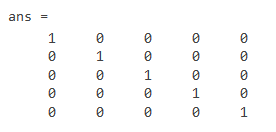

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

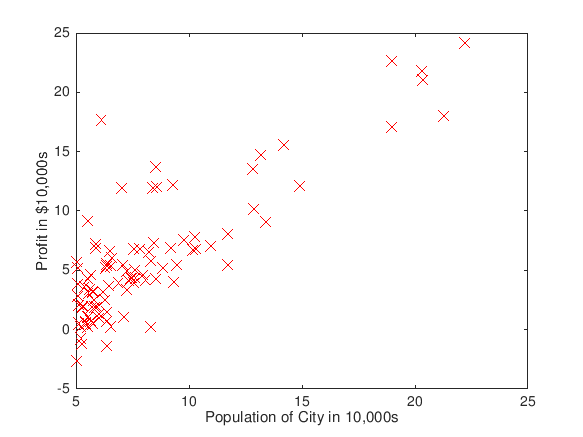

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

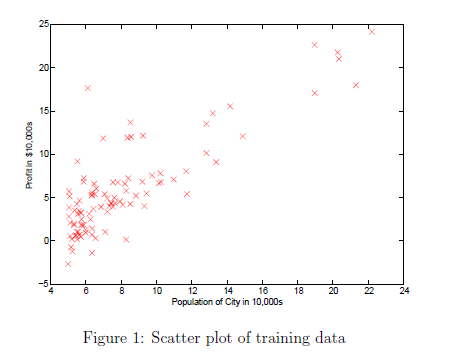

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^{m} {\left(h_{\theta \text{ }} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \text{ }$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\text{ }1}{m}\sum_{i=1}^{m} \text{ }\left(h_{\theta \text{ }} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \text{       }\left(\mathrm{simultaneously}\text{ }\mathrm{update}\text{ }\theta_{j\text{ }} \text{ }\mathrm{for}\text{ }\mathrm{all}\text{ }j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X) % number of training examples

m = 97

X = [ones(m, 1), data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathbf{J}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

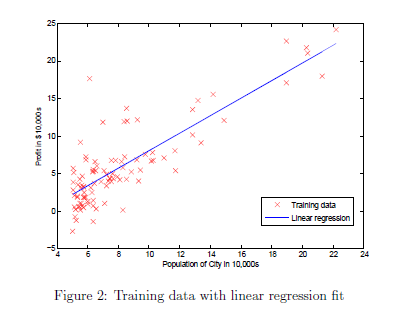    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

update_term =    -5.8391
  -65.3288


theta =     0.0584
    0.6533


update_term =    -0.4500
  -11.6721


theta =     0.0629
    0.7700


update_term =     0.5069
   -2.1338


theta =     0.0578
    0.7913


update_term =     0.6759
   -0.4382


theta =     0.0511
    0.7957


update_term =     0.7049
   -0.1366


theta =     0.0440
    0.7971


update_term =     0.7090
   -0.0829


theta =     0.0369
    0.7979


update_term =     0.7087
   -0.0733


theta =     0.0298
    0.7987


update_term =     0.7076
   -0.0715


theta =     0.0228
    0.7994


update_term =     0.7063
   -0.0710


theta =     0.0157
    0.8001


update_term =     0.7051
   -0.0708


theta =     0.0086
    0.8008


update_term =     0.7038
   -0.0707


theta =     0.0016
    0.8015


update_term =     0.7025
   -0.0706


theta =    -0.0054
    0.8022


update_term =     0.7013
   -0.0705


theta =    -0.0124
    0.8029


update_term =     0.7000
   -0.0703


theta =    -0.0194
    0.8036


update_term =     0.6987
   -0.0702


theta =    -0.0264
    0.8043


update_term =     0.6975
   -0.0701


theta =    -0.0334
    0.8050


update_term =     0.6962
   -0.0699


theta =    -0.0404
    0.8057


update_term =     0.6950
   -0.0698


theta =    -0.0473
    0.8064


update_term =     0.6937
   -0.0697


theta =    -0.0542
    0.8071


update_term =     0.6925
   -0.0696


theta =    -0.0612
    0.8078


update_term =     0.6912
   -0.0694


theta =    -0.0681
    0.8085


update_term =     0.6900
   -0.0693


theta =    -0.0750
    0.8092


update_term =     0.6887
   -0.0692


theta =    -0.0819
    0.8099


update_term =     0.6875
   -0.0691


theta =    -0.0887
    0.8106


update_term =     0.6863
   -0.0689


theta =    -0.0956
    0.8113


update_term =     0.6850
   -0.0688


theta =    -0.1025
    0.8120


update_term =     0.6838
   -0.0687


theta =    -0.1093
    0.8126


update_term =     0.6826
   -0.0686


theta =    -0.1161
    0.8133


update_term =     0.6813
   -0.0684


theta =    -0.1229
    0.8140


update_term =     0.6801
   -0.0683


theta =    -0.1297
    0.8147


update_term =     0.6789
   -0.0682


theta =    -0.1365
    0.8154


update_term =     0.6776
   -0.0681


theta =    -0.1433
    0.8161


update_term =     0.6764
   -0.0680


theta =    -0.1501
    0.8167


update_term =     0.6752
   -0.0678


theta =    -0.1568
    0.8174


update_term =     0.6740
   -0.0677


theta =    -0.1636
    0.8181


update_term =     0.6728
   -0.0676


theta =    -0.1703
    0.8188


update_term =     0.6716
   -0.0675


theta =    -0.1770
    0.8194


update_term =     0.6703
   -0.0673


theta =    -0.1837
    0.8201


update_term =     0.6691
   -0.0672


theta =    -0.1904
    0.8208


update_term =     0.6679
   -0.0671


theta =    -0.1971
    0.8215


update_term =     0.6667
   -0.0670


theta =    -0.2037
    0.8221


update_term =     0.6655
   -0.0669


theta =    -0.2104
    0.8228


update_term =     0.6643
   -0.0667


theta =    -0.2170
    0.8235


update_term =     0.6631
   -0.0666


theta =    -0.2237
    0.8241


update_term =     0.6619
   -0.0665


theta =    -0.2303
    0.8248


update_term =     0.6607
   -0.0664


theta =    -0.2369
    0.8255


update_term =     0.6595
   -0.0663


theta =    -0.2435
    0.8261


update_term =     0.6584
   -0.0661


theta =    -0.2501
    0.8268


update_term =     0.6572
   -0.0660


theta =    -0.2566
    0.8274


update_term =     0.6560
   -0.0659


theta =    -0.2632
    0.8281


update_term =     0.6548
   -0.0658


theta =    -0.2698
    0.8288


update_term =     0.6536
   -0.0657


theta =    -0.2763
    0.8294


update_term =     0.6524
   -0.0655


theta =    -0.2828
    0.8301


update_term =     0.6513
   -0.0654


theta =    -0.2893
    0.8307


update_term =     0.6501
   -0.0653


theta =    -0.2958
    0.8314


update_term =     0.6489
   -0.0652


theta =    -0.3023
    0.8320


update_term =     0.6478
   -0.0651


theta =    -0.3088
    0.8327


update_term =     0.6466
   -0.0650


theta =    -0.3153
    0.8333


update_term =     0.6454
   -0.0648


theta =    -0.3217
    0.8340


update_term =     0.6443
   -0.0647


theta =    -0.3282
    0.8346


update_term =     0.6431
   -0.0646


theta =    -0.3346
    0.8353


update_term =     0.6419
   -0.0645


theta =    -0.3410
    0.8359


update_term =     0.6408
   -0.0644


theta =    -0.3474
    0.8366


update_term =     0.6396
   -0.0643


theta =    -0.3538
    0.8372


update_term =     0.6385
   -0.0641


theta =    -0.3602
    0.8378


update_term =     0.6373
   -0.0640


theta =    -0.3666
    0.8385


update_term =     0.6362
   -0.0639


theta =    -0.3729
    0.8391


update_term =     0.6350
   -0.0638


theta =    -0.3793
    0.8398


update_term =     0.6339
   -0.0637


theta =    -0.3856
    0.8404


update_term =     0.6327
   -0.0636


theta =    -0.3919
    0.8410


update_term =     0.6316
   -0.0635


theta =    -0.3983
    0.8417


update_term =     0.6305
   -0.0633


theta =    -0.4046
    0.8423


update_term =     0.6293
   -0.0632


theta =    -0.4109
    0.8429


update_term =     0.6282
   -0.0631


theta =    -0.4171
    0.8436


update_term =     0.6271
   -0.0630


theta =    -0.4234
    0.8442


update_term =     0.6259
   -0.0629


theta =    -0.4297
    0.8448


update_term =     0.6248
   -0.0628


theta =    -0.4359
    0.8455


update_term =     0.6237
   -0.0627


theta =    -0.4422
    0.8461


update_term =     0.6225
   -0.0625


theta =    -0.4484
    0.8467


update_term =     0.6214
   -0.0624


theta =    -0.4546
    0.8473


update_term =     0.6203
   -0.0623


theta =    -0.4608
    0.8480


update_term =     0.6192
   -0.0622


theta =    -0.4670
    0.8486


update_term =     0.6181
   -0.0621


theta =    -0.4732
    0.8492


update_term =     0.6170
   -0.0620


theta =    -0.4793
    0.8498


update_term =     0.6158
   -0.0619


theta =    -0.4855
    0.8504


update_term =     0.6147
   -0.0618


theta =    -0.4916
    0.8511


update_term =     0.6136
   -0.0616


theta =    -0.4978
    0.8517


update_term =     0.6125
   -0.0615


theta =    -0.5039
    0.8523


update_term =     0.6114
   -0.0614


theta =    -0.5100
    0.8529


update_term =     0.6103
   -0.0613


theta =    -0.5161
    0.8535


update_term =     0.6092
   -0.0612


theta =    -0.5222
    0.8541


update_term =     0.6081
   -0.0611


theta =    -0.5283
    0.8547


update_term =     0.6070
   -0.0610


theta =    -0.5344
    0.8553


update_term =     0.6059
   -0.0609


theta =    -0.5404
    0.8560


update_term =     0.6048
   -0.0608


theta =    -0.5465
    0.8566


update_term =     0.6037
   -0.0607


theta =    -0.5525
    0.8572


update_term =     0.6027
   -0.0605


theta =    -0.5585
    0.8578


update_term =     0.6016
   -0.0604


theta =    -0.5646
    0.8584


update_term =     0.6005
   -0.0603


theta =    -0.5706
    0.8590


update_term =     0.5994
   -0.0602


theta =    -0.5766
    0.8596


update_term =     0.5983
   -0.0601


theta =    -0.5825
    0.8602


update_term =     0.5972
   -0.0600


theta =    -0.5885
    0.8608


update_term =     0.5962
   -0.0599


theta =    -0.5945
    0.8614


update_term =     0.5951
   -0.0598


theta =    -0.6004
    0.8620


update_term =     0.5940
   -0.0597


theta =    -0.6064
    0.8626


update_term =     0.5929
   -0.0596


theta =    -0.6123
    0.8632


update_term =     0.5919
   -0.0595


theta =    -0.6182
    0.8638


update_term =     0.5908
   -0.0594


theta =    -0.6241
    0.8644


update_term =     0.5897
   -0.0592


theta =    -0.6300
    0.8650


update_term =     0.5887
   -0.0591


theta =    -0.6359
    0.8655


update_term =     0.5876
   -0.0590


theta =    -0.6418
    0.8661


update_term =     0.5866
   -0.0589


theta =    -0.6476
    0.8667


update_term =     0.5855
   -0.0588


theta =    -0.6535
    0.8673


update_term =     0.5845
   -0.0587


theta =    -0.6593
    0.8679


update_term =     0.5834
   -0.0586


theta =    -0.6652
    0.8685


update_term =     0.5823
   -0.0585


theta =    -0.6710
    0.8691


update_term =     0.5813
   -0.0584


theta =    -0.6768
    0.8697


update_term =     0.5802
   -0.0583


theta =    -0.6826
    0.8702


update_term =     0.5792
   -0.0582


theta =    -0.6884
    0.8708


update_term =     0.5782
   -0.0581


theta =    -0.6942
    0.8714


update_term =     0.5771
   -0.0580


theta =    -0.7000
    0.8720


update_term =     0.5761
   -0.0579


theta =    -0.7057
    0.8726


update_term =     0.5750
   -0.0578


theta =    -0.7115
    0.8731


update_term =     0.5740
   -0.0577


theta =    -0.7172
    0.8737


update_term =     0.5730
   -0.0576


theta =    -0.7229
    0.8743


update_term =     0.5719
   -0.0575


theta =    -0.7287
    0.8749


update_term =     0.5709
   -0.0574


theta =    -0.7344
    0.8754


update_term =     0.5699
   -0.0573


theta =    -0.7401
    0.8760


update_term =     0.5688
   -0.0571


theta =    -0.7458
    0.8766


update_term =     0.5678
   -0.0570


theta =    -0.7514
    0.8772


update_term =     0.5668
   -0.0569


theta =    -0.7571
    0.8777


update_term =     0.5658
   -0.0568


theta =    -0.7628
    0.8783


update_term =     0.5648
   -0.0567


theta =    -0.7684
    0.8789


update_term =     0.5637
   -0.0566


theta =    -0.7740
    0.8794


update_term =     0.5627
   -0.0565


theta =    -0.7797
    0.8800


update_term =     0.5617
   -0.0564


theta =    -0.7853
    0.8806


update_term =     0.5607
   -0.0563


theta =    -0.7909
    0.8811


update_term =     0.5597
   -0.0562


theta =    -0.7965
    0.8817


update_term =     0.5587
   -0.0561


theta =    -0.8021
    0.8822


update_term =     0.5577
   -0.0560


theta =    -0.8077
    0.8828


update_term =     0.5567
   -0.0559


theta =    -0.8132
    0.8834


update_term =     0.5557
   -0.0558


theta =    -0.8188
    0.8839


update_term =     0.5547
   -0.0557


theta =    -0.8243
    0.8845


update_term =     0.5537
   -0.0556


theta =    -0.8299
    0.8850


update_term =     0.5527
   -0.0555


theta =    -0.8354
    0.8856


update_term =     0.5517
   -0.0554


theta =    -0.8409
    0.8861


update_term =     0.5507
   -0.0553


theta =    -0.8464
    0.8867


update_term =     0.5497
   -0.0552


theta =    -0.8519
    0.8872


update_term =     0.5487
   -0.0551


theta =    -0.8574
    0.8878


update_term =     0.5477
   -0.0550


theta =    -0.8629
    0.8883


update_term =     0.5467
   -0.0549


theta =    -0.8683
    0.8889


update_term =     0.5457
   -0.0548


theta =    -0.8738
    0.8894


update_term =     0.5447
   -0.0547


theta =    -0.8793
    0.8900


update_term =     0.5438
   -0.0546


theta =    -0.8847
    0.8905


update_term =     0.5428
   -0.0545


theta =    -0.8901
    0.8911


update_term =     0.5418
   -0.0544


theta =    -0.8955
    0.8916


update_term =     0.5408
   -0.0543


theta =    -0.9009
    0.8922


update_term =     0.5398
   -0.0542


theta =    -0.9063
    0.8927


update_term =     0.5389
   -0.0541


theta =    -0.9117
    0.8933


update_term =     0.5379
   -0.0540


theta =    -0.9171
    0.8938


update_term =     0.5369
   -0.0539


theta =    -0.9225
    0.8943


update_term =     0.5360
   -0.0538


theta =    -0.9278
    0.8949


update_term =     0.5350
   -0.0537


theta =    -0.9332
    0.8954


update_term =     0.5340
   -0.0536


theta =    -0.9385
    0.8959


update_term =     0.5331
   -0.0536


theta =    -0.9439
    0.8965


update_term =     0.5321
   -0.0535


theta =    -0.9492
    0.8970


update_term =     0.5312
   -0.0534


theta =    -0.9545
    0.8975


update_term =     0.5302
   -0.0533


theta =    -0.9598
    0.8981


update_term =     0.5292
   -0.0532


theta =    -0.9651
    0.8986


update_term =     0.5283
   -0.0531


theta =    -0.9704
    0.8991


update_term =     0.5273
   -0.0530


theta =    -0.9756
    0.8997


update_term =     0.5264
   -0.0529


theta =    -0.9809
    0.9002


update_term =     0.5254
   -0.0528


theta =    -0.9862
    0.9007


update_term =     0.5245
   -0.0527


theta =    -0.9914
    0.9013


update_term =     0.5235
   -0.0526


theta =    -0.9966
    0.9018


update_term =     0.5226
   -0.0525


theta =    -1.0019
    0.9023


update_term =     0.5217
   -0.0524


theta =    -1.0071
    0.9028


update_term =     0.5207
   -0.0523


theta =    -1.0123
    0.9034


update_term =     0.5198
   -0.0522


theta =    -1.0175
    0.9039


update_term =     0.5188
   -0.0521


theta =    -1.0227
    0.9044


update_term =     0.5179
   -0.0520


theta =    -1.0279
    0.9049


update_term =     0.5170
   -0.0519


theta =    -1.0330
    0.9054


update_term =     0.5160
   -0.0518


theta =    -1.0382
    0.9060


update_term =     0.5151
   -0.0517


theta =    -1.0433
    0.9065


update_term =     0.5142
   -0.0517


theta =    -1.0485
    0.9070


update_term =     0.5133
   -0.0516


theta =    -1.0536
    0.9075


update_term =     0.5123
   -0.0515


theta =    -1.0587
    0.9080


update_term =     0.5114
   -0.0514


theta =    -1.0638
    0.9085


update_term =     0.5105
   -0.0513


theta =    -1.0690
    0.9090


update_term =     0.5096
   -0.0512


theta =    -1.0740
    0.9096


update_term =     0.5086
   -0.0511


theta =    -1.0791
    0.9101


update_term =     0.5077
   -0.0510


theta =    -1.0842
    0.9106


update_term =     0.5068
   -0.0509


theta =    -1.0893
    0.9111


update_term =     0.5059
   -0.0508


theta =    -1.0943
    0.9116


update_term =     0.5050
   -0.0507


theta =    -1.0994
    0.9121


update_term =     0.5041
   -0.0506


theta =    -1.1044
    0.9126


update_term =     0.5032
   -0.0505


theta =    -1.1095
    0.9131


update_term =     0.5023
   -0.0505


theta =    -1.1145
    0.9136


update_term =     0.5014
   -0.0504


theta =    -1.1195
    0.9141


update_term =     0.5005
   -0.0503


theta =    -1.1245
    0.9146


update_term =     0.4995
   -0.0502


theta =    -1.1295
    0.9151


update_term =     0.4986
   -0.0501


theta =    -1.1345
    0.9156


update_term =     0.4978
   -0.0500


theta =    -1.1395
    0.9161


update_term =     0.4969
   -0.0499


theta =    -1.1444
    0.9166


update_term =     0.4960
   -0.0498


theta =    -1.1494
    0.9171


update_term =     0.4951
   -0.0497


theta =    -1.1543
    0.9176


update_term =     0.4942
   -0.0496


theta =    -1.1593
    0.9181


update_term =     0.4933
   -0.0496


theta =    -1.1642
    0.9186


update_term =     0.4924
   -0.0495


theta =    -1.1691
    0.9191


update_term =     0.4915
   -0.0494


theta =    -1.1741
    0.9196


update_term =     0.4906
   -0.0493


theta =    -1.1790
    0.9201


update_term =     0.4897
   -0.0492


theta =    -1.1839
    0.9206


update_term =     0.4889
   -0.0491


theta =    -1.1887
    0.9211


update_term =     0.4880
   -0.0490


theta =    -1.1936
    0.9216


update_term =     0.4871
   -0.0489


theta =    -1.1985
    0.9221


update_term =     0.4862
   -0.0488


theta =    -1.2034
    0.9226


update_term =     0.4853
   -0.0488


theta =    -1.2082
    0.9230


update_term =     0.4845
   -0.0487


theta =    -1.2131
    0.9235


update_term =     0.4836
   -0.0486


theta =    -1.2179
    0.9240


update_term =     0.4827
   -0.0485


theta =    -1.2227
    0.9245


update_term =     0.4818
   -0.0484


theta =    -1.2275
    0.9250


update_term =     0.4810
   -0.0483


theta =    -1.2323
    0.9255


update_term =     0.4801
   -0.0482


theta =    -1.2371
    0.9259


update_term =     0.4792
   -0.0481


theta =    -1.2419
    0.9264


update_term =     0.4784
   -0.0481


theta =    -1.2467
    0.9269


update_term =     0.4775
   -0.0480


theta =    -1.2515
    0.9274


update_term =     0.4767
   -0.0479


theta =    -1.2563
    0.9279


update_term =     0.4758
   -0.0478


theta =    -1.2610
    0.9283


update_term =     0.4749
   -0.0477


theta =    -1.2658
    0.9288


update_term =     0.4741
   -0.0476


theta =    -1.2705
    0.9293


update_term =     0.4732
   -0.0475


theta =    -1.2752
    0.9298


update_term =     0.4724
   -0.0475


theta =    -1.2800
    0.9302


update_term =     0.4715
   -0.0474


theta =    -1.2847
    0.9307


update_term =     0.4707
   -0.0473


theta =    -1.2894
    0.9312


update_term =     0.4698
   -0.0472


theta =    -1.2941
    0.9317


update_term =     0.4690
   -0.0471


theta =    -1.2988
    0.9321


update_term =     0.4681
   -0.0470


theta =    -1.3035
    0.9326


update_term =     0.4673
   -0.0469


theta =    -1.3081
    0.9331


update_term =     0.4664
   -0.0469


theta =    -1.3128
    0.9335


update_term =     0.4656
   -0.0468


theta =    -1.3175
    0.9340


update_term =     0.4648
   -0.0467


theta =    -1.3221
    0.9345


update_term =     0.4639
   -0.0466


theta =    -1.3267
    0.9349


update_term =     0.4631
   -0.0465


theta =    -1.3314
    0.9354


update_term =     0.4623
   -0.0464


theta =    -1.3360
    0.9359


update_term =     0.4614
   -0.0464


theta =    -1.3406
    0.9363


update_term =     0.4606
   -0.0463


theta =    -1.3452
    0.9368


update_term =     0.4598
   -0.0462


theta =    -1.3498
    0.9373


update_term =     0.4589
   -0.0461


theta =    -1.3544
    0.9377


update_term =     0.4581
   -0.0460


theta =    -1.3590
    0.9382


update_term =     0.4573
   -0.0459


theta =    -1.3636
    0.9386


update_term =     0.4565
   -0.0459


theta =    -1.3681
    0.9391


update_term =     0.4556
   -0.0458


theta =    -1.3727
    0.9396


update_term =     0.4548
   -0.0457


theta =    -1.3772
    0.9400


update_term =     0.4540
   -0.0456


theta =    -1.3818
    0.9405


update_term =     0.4532
   -0.0455


theta =    -1.3863
    0.9409


update_term =     0.4524
   -0.0454


theta =    -1.3908
    0.9414


update_term =     0.4515
   -0.0454


theta =    -1.3953
    0.9418


update_term =     0.4507
   -0.0453


theta =    -1.3998
    0.9423


update_term =     0.4499
   -0.0452


theta =    -1.4043
    0.9427


update_term =     0.4491
   -0.0451


theta =    -1.4088
    0.9432


update_term =     0.4483
   -0.0450


theta =    -1.4133
    0.9436


update_term =     0.4475
   -0.0450


theta =    -1.4178
    0.9441


update_term =     0.4467
   -0.0449


theta =    -1.4223
    0.9445


update_term =     0.4459
   -0.0448


theta =    -1.4267
    0.9450


update_term =     0.4451
   -0.0447


theta =    -1.4312
    0.9454


update_term =     0.4443
   -0.0446


theta =    -1.4356
    0.9459


update_term =     0.4435
   -0.0446


theta =    -1.4400
    0.9463


update_term =     0.4427
   -0.0445


theta =    -1.4445
    0.9468


update_term =     0.4419
   -0.0444


theta =    -1.4489
    0.9472


update_term =     0.4411
   -0.0443


theta =    -1.4533
    0.9477


update_term =     0.4403
   -0.0442


theta =    -1.4577
    0.9481


update_term =     0.4395
   -0.0442


theta =    -1.4621
    0.9485


update_term =     0.4387
   -0.0441


theta =    -1.4665
    0.9490


update_term =     0.4379
   -0.0440


theta =    -1.4709
    0.9494


update_term =     0.4371
   -0.0439


theta =    -1.4752
    0.9499


update_term =     0.4363
   -0.0438


theta =    -1.4796
    0.9503


update_term =     0.4355
   -0.0438


theta =    -1.4840
    0.9507


update_term =     0.4348
   -0.0437


theta =    -1.4883
    0.9512


update_term =     0.4340
   -0.0436


theta =    -1.4926
    0.9516


update_term =     0.4332
   -0.0435


theta =    -1.4970
    0.9520


update_term =     0.4324
   -0.0434


theta =    -1.5013
    0.9525


update_term =     0.4316
   -0.0434


theta =    -1.5056
    0.9529


update_term =     0.4309
   -0.0433


theta =    -1.5099
    0.9533


update_term =     0.4301
   -0.0432


theta =    -1.5142
    0.9538


update_term =     0.4293
   -0.0431


theta =    -1.5185
    0.9542


update_term =     0.4285
   -0.0430


theta =    -1.5228
    0.9546


update_term =     0.4278
   -0.0430


theta =    -1.5271
    0.9551


update_term =     0.4270
   -0.0429


theta =    -1.5313
    0.9555


update_term =     0.4262
   -0.0428


theta =    -1.5356
    0.9559


update_term =     0.4254
   -0.0427


theta =    -1.5399
    0.9564


update_term =     0.4247
   -0.0427


theta =    -1.5441
    0.9568


update_term =     0.4239
   -0.0426


theta =    -1.5484
    0.9572


update_term =     0.4231
   -0.0425


theta =    -1.5526
    0.9576


update_term =     0.4224
   -0.0424


theta =    -1.5568
    0.9581


update_term =     0.4216
   -0.0424


theta =    -1.5610
    0.9585


update_term =     0.4209
   -0.0423


theta =    -1.5652
    0.9589


update_term =     0.4201
   -0.0422


theta =    -1.5694
    0.9593


update_term =     0.4193
   -0.0421


theta =    -1.5736
    0.9597


update_term =     0.4186
   -0.0421


theta =    -1.5778
    0.9602


update_term =     0.4178
   -0.0420


theta =    -1.5820
    0.9606


update_term =     0.4171
   -0.0419


theta =    -1.5862
    0.9610


update_term =     0.4163
   -0.0418


theta =    -1.5903
    0.9614


update_term =     0.4156
   -0.0417


theta =    -1.5945
    0.9618


update_term =     0.4148
   -0.0417


theta =    -1.5986
    0.9623


update_term =     0.4141
   -0.0416


theta =    -1.6028
    0.9627


update_term =     0.4133
   -0.0415


theta =    -1.6069
    0.9631


update_term =     0.4126
   -0.0414


theta =    -1.6110
    0.9635


update_term =     0.4118
   -0.0414


theta =    -1.6151
    0.9639


update_term =     0.4111
   -0.0413


theta =    -1.6193
    0.9643


update_term =     0.4104
   -0.0412


theta =    -1.6234
    0.9647


update_term =     0.4096
   -0.0412


theta =    -1.6275
    0.9652


update_term =     0.4089
   -0.0411


theta =    -1.6315
    0.9656


update_term =     0.4081
   -0.0410


theta =    -1.6356
    0.9660


update_term =     0.4074
   -0.0409


theta =    -1.6397
    0.9664


update_term =     0.4067
   -0.0409


theta =    -1.6438
    0.9668


update_term =     0.4059
   -0.0408


theta =    -1.6478
    0.9672


update_term =     0.4052
   -0.0407


theta =    -1.6519
    0.9676


update_term =     0.4045
   -0.0406


theta =    -1.6559
    0.9680


update_term =     0.4038
   -0.0406


theta =    -1.6600
    0.9684


update_term =     0.4030
   -0.0405


theta =    -1.6640
    0.9688


update_term =     0.4023
   -0.0404


theta =    -1.6680
    0.9692


update_term =     0.4016
   -0.0403


theta =    -1.6720
    0.9696


update_term =     0.4009
   -0.0403


theta =    -1.6760
    0.9700


update_term =     0.4001
   -0.0402


theta =    -1.6800
    0.9704


update_term =     0.3994
   -0.0401


theta =    -1.6840
    0.9708


update_term =     0.3987
   -0.0401


theta =    -1.6880
    0.9712


update_term =     0.3980
   -0.0400


theta =    -1.6920
    0.9716


update_term =     0.3973
   -0.0399


theta =    -1.6960
    0.9720


update_term =     0.3965
   -0.0398


theta =    -1.6999
    0.9724


update_term =     0.3958
   -0.0398


theta =    -1.7039
    0.9728


update_term =     0.3951
   -0.0397


theta =    -1.7079
    0.9732


update_term =     0.3944
   -0.0396


theta =    -1.7118
    0.9736


update_term =     0.3937
   -0.0395


theta =    -1.7157
    0.9740


update_term =     0.3930
   -0.0395


theta =    -1.7197
    0.9744


update_term =     0.3923
   -0.0394


theta =    -1.7236
    0.9748


update_term =     0.3916
   -0.0393


theta =    -1.7275
    0.9752


update_term =     0.3909
   -0.0393


theta =    -1.7314
    0.9756


update_term =     0.3901
   -0.0392


theta =    -1.7353
    0.9760


update_term =     0.3894
   -0.0391


theta =    -1.7392
    0.9764


update_term =     0.3887
   -0.0391


theta =    -1.7431
    0.9768


update_term =     0.3880
   -0.0390


theta =    -1.7470
    0.9772


update_term =     0.3873
   -0.0389


theta =    -1.7508
    0.9776


update_term =     0.3866
   -0.0388


theta =    -1.7547
    0.9779


update_term =     0.3859
   -0.0388


theta =    -1.7586
    0.9783


update_term =     0.3853
   -0.0387


theta =    -1.7624
    0.9787


update_term =     0.3846
   -0.0386


theta =    -1.7663
    0.9791


update_term =     0.3839
   -0.0386


theta =    -1.7701
    0.9795


update_term =     0.3832
   -0.0385


theta =    -1.7739
    0.9799


update_term =     0.3825
   -0.0384


theta =    -1.7778
    0.9803


update_term =     0.3818
   -0.0384


theta =    -1.7816
    0.9806


update_term =     0.3811
   -0.0383


theta =    -1.7854
    0.9810


update_term =     0.3804
   -0.0382


theta =    -1.7892
    0.9814


update_term =     0.3797
   -0.0381


theta =    -1.7930
    0.9818


update_term =     0.3790
   -0.0381


theta =    -1.7968
    0.9822


update_term =     0.3784
   -0.0380


theta =    -1.8006
    0.9825


update_term =     0.3777
   -0.0379


theta =    -1.8043
    0.9829


update_term =     0.3770
   -0.0379


theta =    -1.8081
    0.9833


update_term =     0.3763
   -0.0378


theta =    -1.8119
    0.9837


update_term =     0.3756
   -0.0377


theta =    -1.8156
    0.9841


update_term =     0.3750
   -0.0377


theta =    -1.8194
    0.9844


update_term =     0.3743
   -0.0376


theta =    -1.8231
    0.9848


update_term =     0.3736
   -0.0375


theta =    -1.8269
    0.9852


update_term =     0.3729
   -0.0375


theta =    -1.8306
    0.9856


update_term =     0.3723
   -0.0374


theta =    -1.8343
    0.9859


update_term =     0.3716
   -0.0373


theta =    -1.8380
    0.9863


update_term =     0.3709
   -0.0373


theta =    -1.8417
    0.9867


update_term =     0.3703
   -0.0372


theta =    -1.8454
    0.9871


update_term =     0.3696
   -0.0371


theta =    -1.8491
    0.9874


update_term =     0.3689
   -0.0371


theta =    -1.8528
    0.9878


update_term =     0.3683
   -0.0370


theta =    -1.8565
    0.9882


update_term =     0.3676
   -0.0369


theta =    -1.8602
    0.9885


update_term =     0.3669
   -0.0369


theta =    -1.8639
    0.9889


update_term =     0.3663
   -0.0368


theta =    -1.8675
    0.9893


update_term =     0.3656
   -0.0367


theta =    -1.8712
    0.9896


update_term =     0.3650
   -0.0367


theta =    -1.8748
    0.9900


update_term =     0.3643
   -0.0366


theta =    -1.8785
    0.9904


update_term =     0.3636
   -0.0365


theta =    -1.8821
    0.9907


update_term =     0.3630
   -0.0365


theta =    -1.8857
    0.9911


update_term =     0.3623
   -0.0364


theta =    -1.8894
    0.9915


update_term =     0.3617
   -0.0363


theta =    -1.8930
    0.9918


update_term =     0.3610
   -0.0363


theta =    -1.8966
    0.9922


update_term =     0.3604
   -0.0362


theta =    -1.9002
    0.9926


update_term =     0.3597
   -0.0361


theta =    -1.9038
    0.9929


update_term =     0.3591
   -0.0361


theta =    -1.9074
    0.9933


update_term =     0.3584
   -0.0360


theta =    -1.9110
    0.9936


update_term =     0.3578
   -0.0359


theta =    -1.9145
    0.9940


update_term =     0.3571
   -0.0359


theta =    -1.9181
    0.9944


update_term =     0.3565
   -0.0358


theta =    -1.9217
    0.9947


update_term =     0.3559
   -0.0357


theta =    -1.9252
    0.9951


update_term =     0.3552
   -0.0357


theta =    -1.9288
    0.9954


update_term =     0.3546
   -0.0356


theta =    -1.9323
    0.9958


update_term =     0.3539
   -0.0356


theta =    -1.9359
    0.9961


update_term =     0.3533
   -0.0355


theta =    -1.9394
    0.9965


update_term =     0.3527
   -0.0354


theta =    -1.9429
    0.9968


update_term =     0.3520
   -0.0354


theta =    -1.9465
    0.9972


update_term =     0.3514
   -0.0353


theta =    -1.9500
    0.9976


update_term =     0.3508
   -0.0352


theta =    -1.9535
    0.9979


update_term =     0.3501
   -0.0352


theta =    -1.9570
    0.9983


update_term =     0.3495
   -0.0351


theta =    -1.9605
    0.9986


update_term =     0.3489
   -0.0350


theta =    -1.9640
    0.9990


update_term =     0.3482
   -0.0350


theta =    -1.9674
    0.9993


update_term =     0.3476
   -0.0349


theta =    -1.9709
    0.9997


update_term =     0.3470
   -0.0349


theta =    -1.9744
    1.0000


update_term =     0.3463
   -0.0348


theta =    -1.9778
    1.0004


update_term =     0.3457
   -0.0347


theta =    -1.9813
    1.0007


update_term =     0.3451
   -0.0347


theta =    -1.9848
    1.0011


update_term =     0.3445
   -0.0346


theta =    -1.9882
    1.0014


update_term =     0.3439
   -0.0345


theta =    -1.9916
    1.0017


update_term =     0.3432
   -0.0345


theta =    -1.9951
    1.0021


update_term =     0.3426
   -0.0344


theta =    -1.9985
    1.0024


update_term =     0.3420
   -0.0344


theta =    -2.0019
    1.0028


update_term =     0.3414
   -0.0343


theta =    -2.0053
    1.0031


update_term =     0.3408
   -0.0342


theta =    -2.0087
    1.0035


update_term =     0.3402
   -0.0342


theta =    -2.0121
    1.0038


update_term =     0.3395
   -0.0341


theta =    -2.0155
    1.0041


update_term =     0.3389
   -0.0340


theta =    -2.0189
    1.0045


update_term =     0.3383
   -0.0340


theta =    -2.0223
    1.0048


update_term =     0.3377
   -0.0339


theta =    -2.0257
    1.0052


update_term =     0.3371
   -0.0339


theta =    -2.0291
    1.0055


update_term =     0.3365
   -0.0338


theta =    -2.0324
    1.0058


update_term =     0.3359
   -0.0337


theta =    -2.0358
    1.0062


update_term =     0.3353
   -0.0337


theta =    -2.0391
    1.0065


update_term =     0.3347
   -0.0336


theta =    -2.0425
    1.0068


update_term =     0.3341
   -0.0336


theta =    -2.0458
    1.0072


update_term =     0.3335
   -0.0335


theta =    -2.0492
    1.0075


update_term =     0.3329
   -0.0334


theta =    -2.0525
    1.0079


update_term =     0.3323
   -0.0334


theta =    -2.0558
    1.0082


update_term =     0.3317
   -0.0333


theta =    -2.0591
    1.0085


update_term =     0.3311
   -0.0333


theta =    -2.0624
    1.0089


update_term =     0.3305
   -0.0332


theta =    -2.0657
    1.0092


update_term =     0.3299
   -0.0331


theta =    -2.0690
    1.0095


update_term =     0.3293
   -0.0331


theta =    -2.0723
    1.0098


update_term =     0.3287
   -0.0330


theta =    -2.0756
    1.0102


update_term =     0.3281
   -0.0330


theta =    -2.0789
    1.0105


update_term =     0.3275
   -0.0329


theta =    -2.0822
    1.0108


update_term =     0.3269
   -0.0328


theta =    -2.0854
    1.0112


update_term =     0.3263
   -0.0328


theta =    -2.0887
    1.0115


update_term =     0.3257
   -0.0327


theta =    -2.0920
    1.0118


update_term =     0.3252
   -0.0327


theta =    -2.0952
    1.0121


update_term =     0.3246
   -0.0326


theta =    -2.0985
    1.0125


update_term =     0.3240
   -0.0325


theta =    -2.1017
    1.0128


update_term =     0.3234
   -0.0325


theta =    -2.1049
    1.0131


update_term =     0.3228
   -0.0324


theta =    -2.1082
    1.0134


update_term =     0.3222
   -0.0324


theta =    -2.1114
    1.0138


update_term =     0.3217
   -0.0323


theta =    -2.1146
    1.0141


update_term =     0.3211
   -0.0323


theta =    -2.1178
    1.0144


update_term =     0.3205
   -0.0322


theta =    -2.1210
    1.0147


update_term =     0.3199
   -0.0321


theta =    -2.1242
    1.0151


update_term =     0.3193
   -0.0321


theta =    -2.1274
    1.0154


update_term =     0.3188
   -0.0320


theta =    -2.1306
    1.0157


update_term =     0.3182
   -0.0320


theta =    -2.1338
    1.0160


update_term =     0.3176
   -0.0319


theta =    -2.1370
    1.0163


update_term =     0.3170
   -0.0319


theta =    -2.1401
    1.0167


update_term =     0.3165
   -0.0318


theta =    -2.1433
    1.0170


update_term =     0.3159
   -0.0317


theta =    -2.1465
    1.0173


update_term =     0.3153
   -0.0317


theta =    -2.1496
    1.0176


update_term =     0.3148
   -0.0316


theta =    -2.1528
    1.0179


update_term =     0.3142
   -0.0316


theta =    -2.1559
    1.0182


update_term =     0.3136
   -0.0315


theta =    -2.1590
    1.0186


update_term =     0.3131
   -0.0315


theta =    -2.1622
    1.0189


update_term =     0.3125
   -0.0314


theta =    -2.1653
    1.0192


update_term =     0.3119
   -0.0313


theta =    -2.1684
    1.0195


update_term =     0.3114
   -0.0313


theta =    -2.1715
    1.0198


update_term =     0.3108
   -0.0312


theta =    -2.1746
    1.0201


update_term =     0.3103
   -0.0312


theta =    -2.1777
    1.0204


update_term =     0.3097
   -0.0311


theta =    -2.1808
    1.0207


update_term =     0.3091
   -0.0311


theta =    -2.1839
    1.0211


update_term =     0.3086
   -0.0310


theta =    -2.1870
    1.0214


update_term =     0.3080
   -0.0309


theta =    -2.1901
    1.0217


update_term =     0.3075
   -0.0309


theta =    -2.1932
    1.0220


update_term =     0.3069
   -0.0308


theta =    -2.1962
    1.0223


update_term =     0.3064
   -0.0308


theta =    -2.1993
    1.0226


update_term =     0.3058
   -0.0307


theta =    -2.2024
    1.0229


update_term =     0.3053
   -0.0307


theta =    -2.2054
    1.0232


update_term =     0.3047
   -0.0306


theta =    -2.2085
    1.0235


update_term =     0.3042
   -0.0306


theta =    -2.2115
    1.0238


update_term =     0.3036
   -0.0305


theta =    -2.2145
    1.0241


update_term =     0.3031
   -0.0304


theta =    -2.2176
    1.0244


update_term =     0.3025
   -0.0304


theta =    -2.2206
    1.0247


update_term =     0.3020
   -0.0303


theta =    -2.2236
    1.0250


update_term =     0.3014
   -0.0303


theta =    -2.2266
    1.0253


update_term =     0.3009
   -0.0302


theta =    -2.2296
    1.0257


update_term =     0.3003
   -0.0302


theta =    -2.2326
    1.0260


update_term =     0.2998
   -0.0301


theta =    -2.2356
    1.0263


update_term =     0.2993
   -0.0301


theta =    -2.2386
    1.0266


update_term =     0.2987
   -0.0300


theta =    -2.2416
    1.0269


update_term =     0.2982
   -0.0300


theta =    -2.2446
    1.0272


update_term =     0.2976
   -0.0299


theta =    -2.2476
    1.0275


update_term =     0.2971
   -0.0298


theta =    -2.2505
    1.0278


update_term =     0.2966
   -0.0298


theta =    -2.2535
    1.0280


update_term =     0.2960
   -0.0297


theta =    -2.2565
    1.0283


update_term =     0.2955
   -0.0297


theta =    -2.2594
    1.0286


update_term =     0.2950
   -0.0296


theta =    -2.2624
    1.0289


update_term =     0.2944
   -0.0296


theta =    -2.2653
    1.0292


update_term =     0.2939
   -0.0295


theta =    -2.2683
    1.0295


update_term =     0.2934
   -0.0295


theta =    -2.2712
    1.0298


update_term =     0.2928
   -0.0294


theta =    -2.2741
    1.0301


update_term =     0.2923
   -0.0294


theta =    -2.2770
    1.0304


update_term =     0.2918
   -0.0293


theta =    -2.2800
    1.0307


update_term =     0.2913
   -0.0293


theta =    -2.2829
    1.0310


update_term =     0.2907
   -0.0292


theta =    -2.2858
    1.0313


update_term =     0.2902
   -0.0292


theta =    -2.2887
    1.0316


update_term =     0.2897
   -0.0291


theta =    -2.2916
    1.0319


update_term =     0.2892
   -0.0291


theta =    -2.2945
    1.0322


update_term =     0.2887
   -0.0290


theta =    -2.2974
    1.0325


update_term =     0.2881
   -0.0289


theta =    -2.3002
    1.0327


update_term =     0.2876
   -0.0289


theta =    -2.3031
    1.0330


update_term =     0.2871
   -0.0288


theta =    -2.3060
    1.0333


update_term =     0.2866
   -0.0288


theta =    -2.3088
    1.0336


update_term =     0.2861
   -0.0287


theta =    -2.3117
    1.0339


update_term =     0.2855
   -0.0287


theta =    -2.3146
    1.0342


update_term =     0.2850
   -0.0286


theta =    -2.3174
    1.0345


update_term =     0.2845
   -0.0286


theta =    -2.3203
    1.0348


update_term =     0.2840
   -0.0285


theta =    -2.3231
    1.0350


update_term =     0.2835
   -0.0285


theta =    -2.3259
    1.0353


update_term =     0.2830
   -0.0284


theta =    -2.3288
    1.0356


update_term =     0.2825
   -0.0284


theta =    -2.3316
    1.0359


update_term =     0.2820
   -0.0283


theta =    -2.3344
    1.0362


update_term =     0.2815
   -0.0283


theta =    -2.3372
    1.0365


update_term =     0.2809
   -0.0282


theta =    -2.3400
    1.0367


update_term =     0.2804
   -0.0282


theta =    -2.3428
    1.0370


update_term =     0.2799
   -0.0281


theta =    -2.3456
    1.0373


update_term =     0.2794
   -0.0281


theta =    -2.3484
    1.0376


update_term =     0.2789
   -0.0280


theta =    -2.3512
    1.0379


update_term =     0.2784
   -0.0280


theta =    -2.3540
    1.0381


update_term =     0.2779
   -0.0279


theta =    -2.3568
    1.0384


update_term =     0.2774
   -0.0279


theta =    -2.3596
    1.0387


update_term =     0.2769
   -0.0278


theta =    -2.3623
    1.0390


update_term =     0.2764
   -0.0278


theta =    -2.3651
    1.0393


update_term =     0.2759
   -0.0277


theta =    -2.3678
    1.0395


update_term =     0.2754
   -0.0277


theta =    -2.3706
    1.0398


update_term =     0.2749
   -0.0276


theta =    -2.3734
    1.0401


update_term =     0.2744
   -0.0276


theta =    -2.3761
    1.0404


update_term =     0.2739
   -0.0275


theta =    -2.3788
    1.0406


update_term =     0.2734
   -0.0275


theta =    -2.3816
    1.0409


update_term =     0.2730
   -0.0274


theta =    -2.3843
    1.0412


update_term =     0.2725
   -0.0274


theta =    -2.3870
    1.0415


update_term =     0.2720
   -0.0273


theta =    -2.3897
    1.0417


update_term =     0.2715
   -0.0273


theta =    -2.3925
    1.0420


update_term =     0.2710
   -0.0272


theta =    -2.3952
    1.0423


update_term =     0.2705
   -0.0272


theta =    -2.3979
    1.0426


update_term =     0.2700
   -0.0271


theta =    -2.4006
    1.0428


update_term =     0.2695
   -0.0271


theta =    -2.4033
    1.0431


update_term =     0.2690
   -0.0270


theta =    -2.4060
    1.0434


update_term =     0.2686
   -0.0270


theta =    -2.4086
    1.0436


update_term =     0.2681
   -0.0269


theta =    -2.4113
    1.0439


update_term =     0.2676
   -0.0269


theta =    -2.4140
    1.0442


update_term =     0.2671
   -0.0268


theta =    -2.4167
    1.0444


update_term =     0.2666
   -0.0268


theta =    -2.4193
    1.0447


update_term =     0.2661
   -0.0267


theta =    -2.4220
    1.0450


update_term =     0.2657
   -0.0267


theta =    -2.4247
    1.0452


update_term =     0.2652
   -0.0266


theta =    -2.4273
    1.0455


update_term =     0.2647
   -0.0266


theta =    -2.4300
    1.0458


update_term =     0.2642
   -0.0265


theta =    -2.4326
    1.0460


update_term =     0.2638
   -0.0265


theta =    -2.4352
    1.0463


update_term =     0.2633
   -0.0264


theta =    -2.4379
    1.0466


update_term =     0.2628
   -0.0264


theta =    -2.4405
    1.0468


update_term =     0.2623
   -0.0264


theta =    -2.4431
    1.0471


update_term =     0.2619
   -0.0263


theta =    -2.4457
    1.0474


update_term =     0.2614
   -0.0263


theta =    -2.4484
    1.0476


update_term =     0.2609
   -0.0262


theta =    -2.4510
    1.0479


update_term =     0.2604
   -0.0262


theta =    -2.4536
    1.0481


update_term =     0.2600
   -0.0261


theta =    -2.4562
    1.0484


update_term =     0.2595
   -0.0261


theta =    -2.4588
    1.0487


update_term =     0.2590
   -0.0260


theta =    -2.4614
    1.0489


update_term =     0.2586
   -0.0260


theta =    -2.4639
    1.0492


update_term =     0.2581
   -0.0259


theta =    -2.4665
    1.0494


update_term =     0.2576
   -0.0259


theta =    -2.4691
    1.0497


update_term =     0.2572
   -0.0258


theta =    -2.4717
    1.0500


update_term =     0.2567
   -0.0258


theta =    -2.4742
    1.0502


update_term =     0.2562
   -0.0257


theta =    -2.4768
    1.0505


update_term =     0.2558
   -0.0257


theta =    -2.4794
    1.0507


update_term =     0.2553
   -0.0257


theta =    -2.4819
    1.0510


update_term =     0.2549
   -0.0256


theta =    -2.4845
    1.0513


update_term =     0.2544
   -0.0256


theta =    -2.4870
    1.0515


update_term =     0.2539
   -0.0255


theta =    -2.4895
    1.0518


update_term =     0.2535
   -0.0255


theta =    -2.4921
    1.0520


update_term =     0.2530
   -0.0254


theta =    -2.4946
    1.0523


update_term =     0.2526
   -0.0254


theta =    -2.4971
    1.0525


update_term =     0.2521
   -0.0253


theta =    -2.4997
    1.0528


update_term =     0.2517
   -0.0253


theta =    -2.5022
    1.0530


update_term =     0.2512
   -0.0252


theta =    -2.5047
    1.0533


update_term =     0.2508
   -0.0252


theta =    -2.5072
    1.0535


update_term =     0.2503
   -0.0251


theta =    -2.5097
    1.0538


update_term =     0.2499
   -0.0251


theta =    -2.5122
    1.0540


update_term =     0.2494
   -0.0251


theta =    -2.5147
    1.0543


update_term =     0.2490
   -0.0250


theta =    -2.5172
    1.0545


update_term =     0.2485
   -0.0250


theta =    -2.5197
    1.0548


update_term =     0.2481
   -0.0249


theta =    -2.5221
    1.0550


update_term =     0.2476
   -0.0249


theta =    -2.5246
    1.0553


update_term =     0.2472
   -0.0248


theta =    -2.5271
    1.0555


update_term =     0.2467
   -0.0248


theta =    -2.5296
    1.0558


update_term =     0.2463
   -0.0247


theta =    -2.5320
    1.0560


update_term =     0.2458
   -0.0247


theta =    -2.5345
    1.0563


update_term =     0.2454
   -0.0247


theta =    -2.5369
    1.0565


update_term =     0.2449
   -0.0246


theta =    -2.5394
    1.0568


update_term =     0.2445
   -0.0246


theta =    -2.5418
    1.0570


update_term =     0.2441
   -0.0245


theta =    -2.5443
    1.0573


update_term =     0.2436
   -0.0245


theta =    -2.5467
    1.0575


update_term =     0.2432
   -0.0244


theta =    -2.5491
    1.0577


update_term =     0.2427
   -0.0244


theta =    -2.5516
    1.0580


update_term =     0.2423
   -0.0243


theta =    -2.5540
    1.0582


update_term =     0.2419
   -0.0243


theta =    -2.5564
    1.0585


update_term =     0.2414
   -0.0243


theta =    -2.5588
    1.0587


update_term =     0.2410
   -0.0242


theta =    -2.5612
    1.0590


update_term =     0.2406
   -0.0242


theta =    -2.5636
    1.0592


update_term =     0.2401
   -0.0241


theta =    -2.5660
    1.0594


update_term =     0.2397
   -0.0241


theta =    -2.5684
    1.0597


update_term =     0.2393
   -0.0240


theta =    -2.5708
    1.0599


update_term =     0.2388
   -0.0240


theta =    -2.5732
    1.0602


update_term =     0.2384
   -0.0240


theta =    -2.5756
    1.0604


update_term =     0.2380
   -0.0239


theta =    -2.5780
    1.0606


update_term =     0.2375
   -0.0239


theta =    -2.5803
    1.0609


update_term =     0.2371
   -0.0238


theta =    -2.5827
    1.0611


update_term =     0.2367
   -0.0238


theta =    -2.5851
    1.0614


update_term =     0.2363
   -0.0237


theta =    -2.5874
    1.0616


update_term =     0.2358
   -0.0237


theta =    -2.5898
    1.0618


update_term =     0.2354
   -0.0236


theta =    -2.5922
    1.0621


update_term =     0.2350
   -0.0236


theta =    -2.5945
    1.0623


update_term =     0.2346
   -0.0236


theta =    -2.5969
    1.0625


update_term =     0.2341
   -0.0235


theta =    -2.5992
    1.0628


update_term =     0.2337
   -0.0235


theta =    -2.6015
    1.0630


update_term =     0.2333
   -0.0234


theta =    -2.6039
    1.0632


update_term =     0.2329
   -0.0234


theta =    -2.6062
    1.0635


update_term =     0.2325
   -0.0234


theta =    -2.6085
    1.0637


update_term =     0.2320
   -0.0233


theta =    -2.6108
    1.0639


update_term =     0.2316
   -0.0233


theta =    -2.6132
    1.0642


update_term =     0.2312
   -0.0232


theta =    -2.6155
    1.0644


update_term =     0.2308
   -0.0232


theta =    -2.6178
    1.0646


update_term =     0.2304
   -0.0231


theta =    -2.6201
    1.0649


update_term =     0.2300
   -0.0231


theta =    -2.6224
    1.0651


update_term =     0.2295
   -0.0231


theta =    -2.6247
    1.0653


update_term =     0.2291
   -0.0230


theta =    -2.6270
    1.0656


update_term =     0.2287
   -0.0230


theta =    -2.6293
    1.0658


update_term =     0.2283
   -0.0229


theta =    -2.6315
    1.0660


update_term =     0.2279
   -0.0229


theta =    -2.6338
    1.0663


update_term =     0.2275
   -0.0229


theta =    -2.6361
    1.0665


update_term =     0.2271
   -0.0228


theta =    -2.6384
    1.0667


update_term =     0.2267
   -0.0228


theta =    -2.6406
    1.0669


update_term =     0.2263
   -0.0227


theta =    -2.6429
    1.0672


update_term =     0.2258
   -0.0227


theta =    -2.6452
    1.0674


update_term =     0.2254
   -0.0226


theta =    -2.6474
    1.0676


update_term =     0.2250
   -0.0226


theta =    -2.6497
    1.0678


update_term =     0.2246
   -0.0226


theta =    -2.6519
    1.0681


update_term =     0.2242
   -0.0225


theta =    -2.6541
    1.0683


update_term =     0.2238
   -0.0225


theta =    -2.6564
    1.0685


update_term =     0.2234
   -0.0224


theta =    -2.6586
    1.0687


update_term =     0.2230
   -0.0224


theta =    -2.6608
    1.0690


update_term =     0.2226
   -0.0224


theta =    -2.6631
    1.0692


update_term =     0.2222
   -0.0223


theta =    -2.6653
    1.0694


update_term =     0.2218
   -0.0223


theta =    -2.6675
    1.0696


update_term =     0.2214
   -0.0222


theta =    -2.6697
    1.0699


update_term =     0.2210
   -0.0222


theta =    -2.6719
    1.0701


update_term =     0.2206
   -0.0222


theta =    -2.6741
    1.0703


update_term =     0.2202
   -0.0221


theta =    -2.6763
    1.0705


update_term =     0.2198
   -0.0221


theta =    -2.6785
    1.0707


update_term =     0.2194
   -0.0220


theta =    -2.6807
    1.0710


update_term =     0.2190
   -0.0220


theta =    -2.6829
    1.0712


update_term =     0.2186
   -0.0220


theta =    -2.6851
    1.0714


update_term =     0.2182
   -0.0219


theta =    -2.6873
    1.0716


update_term =     0.2178
   -0.0219


theta =    -2.6895
    1.0718


update_term =     0.2174
   -0.0218


theta =    -2.6916
    1.0721


update_term =     0.2171
   -0.0218


theta =    -2.6938
    1.0723


update_term =     0.2167
   -0.0218


theta =    -2.6960
    1.0725


update_term =     0.2163
   -0.0217


theta =    -2.6981
    1.0727


update_term =     0.2159
   -0.0217


theta =    -2.7003
    1.0729


update_term =     0.2155
   -0.0216


theta =    -2.7025
    1.0732


update_term =     0.2151
   -0.0216


theta =    -2.7046
    1.0734


update_term =     0.2147
   -0.0216


theta =    -2.7068
    1.0736


update_term =     0.2143
   -0.0215


theta =    -2.7089
    1.0738


update_term =     0.2139
   -0.0215


theta =    -2.7110
    1.0740


update_term =     0.2136
   -0.0215


theta =    -2.7132
    1.0742


update_term =     0.2132
   -0.0214


theta =    -2.7153
    1.0744


update_term =     0.2128
   -0.0214


theta =    -2.7174
    1.0747


update_term =     0.2124
   -0.0213


theta =    -2.7196
    1.0749


update_term =     0.2120
   -0.0213


theta =    -2.7217
    1.0751


update_term =     0.2116
   -0.0213


theta =    -2.7238
    1.0753


update_term =     0.2113
   -0.0212


theta =    -2.7259
    1.0755


update_term =     0.2109
   -0.0212


theta =    -2.7280
    1.0757


update_term =     0.2105
   -0.0211


theta =    -2.7301
    1.0759


update_term =     0.2101
   -0.0211


theta =    -2.7322
    1.0761


update_term =     0.2097
   -0.0211


theta =    -2.7343
    1.0764


update_term =     0.2094
   -0.0210


theta =    -2.7364
    1.0766


update_term =     0.2090
   -0.0210


theta =    -2.7385
    1.0768


update_term =     0.2086
   -0.0210


theta =    -2.7406
    1.0770


update_term =     0.2082
   -0.0209


theta =    -2.7427
    1.0772


update_term =     0.2079
   -0.0209


theta =    -2.7448
    1.0774


update_term =     0.2075
   -0.0208


theta =    -2.7468
    1.0776


update_term =     0.2071
   -0.0208


theta =    -2.7489
    1.0778


update_term =     0.2067
   -0.0208


theta =    -2.7510
    1.0780


update_term =     0.2064
   -0.0207


theta =    -2.7530
    1.0782


update_term =     0.2060
   -0.0207


theta =    -2.7551
    1.0784


update_term =     0.2056
   -0.0207


theta =    -2.7571
    1.0786


update_term =     0.2052
   -0.0206


theta =    -2.7592
    1.0789


update_term =     0.2049
   -0.0206


theta =    -2.7613
    1.0791


update_term =     0.2045
   -0.0205


theta =    -2.7633
    1.0793


update_term =     0.2041
   -0.0205


theta =    -2.7653
    1.0795


update_term =     0.2038
   -0.0205


theta =    -2.7674
    1.0797


update_term =     0.2034
   -0.0204


theta =    -2.7694
    1.0799


update_term =     0.2030
   -0.0204


theta =    -2.7714
    1.0801


update_term =     0.2027
   -0.0204


theta =    -2.7735
    1.0803


update_term =     0.2023
   -0.0203


theta =    -2.7755
    1.0805


update_term =     0.2019
   -0.0203


theta =    -2.7775
    1.0807


update_term =     0.2016
   -0.0203


theta =    -2.7795
    1.0809


update_term =     0.2012
   -0.0202


theta =    -2.7815
    1.0811


update_term =     0.2009
   -0.0202


theta =    -2.7835
    1.0813


update_term =     0.2005
   -0.0201


theta =    -2.7855
    1.0815


update_term =     0.2001
   -0.0201


theta =    -2.7876
    1.0817


update_term =     0.1998
   -0.0201


theta =    -2.7895
    1.0819


update_term =     0.1994
   -0.0200


theta =    -2.7915
    1.0821


update_term =     0.1990
   -0.0200


theta =    -2.7935
    1.0823


update_term =     0.1987
   -0.0200


theta =    -2.7955
    1.0825


update_term =     0.1983
   -0.0199


theta =    -2.7975
    1.0827


update_term =     0.1980
   -0.0199


theta =    -2.7995
    1.0829


update_term =     0.1976
   -0.0199


theta =    -2.8015
    1.0831


update_term =     0.1973
   -0.0198


theta =    -2.8034
    1.0833


update_term =     0.1969
   -0.0198


theta =    -2.8054
    1.0835


update_term =     0.1966
   -0.0197


theta =    -2.8074
    1.0837


update_term =     0.1962
   -0.0197


theta =    -2.8093
    1.0839


update_term =     0.1958
   -0.0197


theta =    -2.8113
    1.0841


update_term =     0.1955
   -0.0196


theta =    -2.8132
    1.0843


update_term =     0.1951
   -0.0196


theta =    -2.8152
    1.0845


update_term =     0.1948
   -0.0196


theta =    -2.8171
    1.0847


update_term =     0.1944
   -0.0195


theta =    -2.8191
    1.0849


update_term =     0.1941
   -0.0195


theta =    -2.8210
    1.0851


update_term =     0.1937
   -0.0195


theta =    -2.8230
    1.0853


update_term =     0.1934
   -0.0194


theta =    -2.8249
    1.0855


update_term =     0.1930
   -0.0194


theta =    -2.8268
    1.0856


update_term =     0.1927
   -0.0194


theta =    -2.8288
    1.0858


update_term =     0.1923
   -0.0193


theta =    -2.8307
    1.0860


update_term =     0.1920
   -0.0193


theta =    -2.8326
    1.0862


update_term =     0.1916
   -0.0193


theta =    -2.8345
    1.0864


update_term =     0.1913
   -0.0192


theta =    -2.8364
    1.0866


update_term =     0.1910
   -0.0192


theta =    -2.8383
    1.0868


update_term =     0.1906
   -0.0191


theta =    -2.8402
    1.0870


update_term =     0.1903
   -0.0191


theta =    -2.8421
    1.0872


update_term =     0.1899
   -0.0191


theta =    -2.8440
    1.0874


update_term =     0.1896
   -0.0190


theta =    -2.8459
    1.0876


update_term =     0.1892
   -0.0190


theta =    -2.8478
    1.0878


update_term =     0.1889
   -0.0190


theta =    -2.8497
    1.0879


update_term =     0.1886
   -0.0189


theta =    -2.8516
    1.0881


update_term =     0.1882
   -0.0189


theta =    -2.8535
    1.0883


update_term =     0.1879
   -0.0189


theta =    -2.8554
    1.0885


update_term =     0.1875
   -0.0188


theta =    -2.8572
    1.0887


update_term =     0.1872
   -0.0188


theta =    -2.8591
    1.0889


update_term =     0.1869
   -0.0188


theta =    -2.8610
    1.0891


update_term =     0.1865
   -0.0187


theta =    -2.8629
    1.0893


update_term =     0.1862
   -0.0187


theta =    -2.8647
    1.0895


update_term =     0.1859
   -0.0187


theta =    -2.8666
    1.0896


update_term =     0.1855
   -0.0186


theta =    -2.8684
    1.0898


update_term =     0.1852
   -0.0186


theta =    -2.8703
    1.0900


update_term =     0.1849
   -0.0186


theta =    -2.8721
    1.0902


update_term =     0.1845
   -0.0185


theta =    -2.8740
    1.0904


update_term =     0.1842
   -0.0185


theta =    -2.8758
    1.0906


update_term =     0.1839
   -0.0185


theta =    -2.8777
    1.0908


update_term =     0.1835
   -0.0184


theta =    -2.8795
    1.0909


update_term =     0.1832
   -0.0184


theta =    -2.8813
    1.0911


update_term =     0.1829
   -0.0184


theta =    -2.8831
    1.0913


update_term =     0.1825
   -0.0183


theta =    -2.8850
    1.0915


update_term =     0.1822
   -0.0183


theta =    -2.8868
    1.0917


update_term =     0.1819
   -0.0183


theta =    -2.8886
    1.0919


update_term =     0.1816
   -0.0182


theta =    -2.8904
    1.0920


update_term =     0.1812
   -0.0182


theta =    -2.8922
    1.0922


update_term =     0.1809
   -0.0182


theta =    -2.8941
    1.0924


update_term =     0.1806
   -0.0181


theta =    -2.8959
    1.0926


update_term =     0.1802
   -0.0181


theta =    -2.8977
    1.0928


update_term =     0.1799
   -0.0181


theta =    -2.8995
    1.0929


update_term =     0.1796
   -0.0180


theta =    -2.9013
    1.0931


update_term =     0.1793
   -0.0180


theta =    -2.9030
    1.0933


update_term =     0.1789
   -0.0180


theta =    -2.9048
    1.0935


update_term =     0.1786
   -0.0179


theta =    -2.9066
    1.0937


update_term =     0.1783
   -0.0179


theta =    -2.9084
    1.0938


update_term =     0.1780
   -0.0179


theta =    -2.9102
    1.0940


update_term =     0.1777
   -0.0178


theta =    -2.9120
    1.0942


update_term =     0.1773
   -0.0178


theta =    -2.9137
    1.0944


update_term =     0.1770
   -0.0178


theta =    -2.9155
    1.0946


update_term =     0.1767
   -0.0178


theta =    -2.9173
    1.0947


update_term =     0.1764
   -0.0177


theta =    -2.9190
    1.0949


update_term =     0.1761
   -0.0177


theta =    -2.9208
    1.0951


update_term =     0.1757
   -0.0177


theta =    -2.9226
    1.0953


update_term =     0.1754
   -0.0176


theta =    -2.9243
    1.0954


update_term =     0.1751
   -0.0176


theta =    -2.9261
    1.0956


update_term =     0.1748
   -0.0176


theta =    -2.9278
    1.0958


update_term =     0.1745
   -0.0175


theta =    -2.9296
    1.0960


update_term =     0.1742
   -0.0175


theta =    -2.9313
    1.0961


update_term =     0.1739
   -0.0175


theta =    -2.9330
    1.0963


update_term =     0.1735
   -0.0174


theta =    -2.9348
    1.0965


update_term =     0.1732
   -0.0174


theta =    -2.9365
    1.0967


update_term =     0.1729
   -0.0174


theta =    -2.9382
    1.0968


update_term =     0.1726
   -0.0173


theta =    -2.9400
    1.0970


update_term =     0.1723
   -0.0173


theta =    -2.9417
    1.0972


update_term =     0.1720
   -0.0173


theta =    -2.9434
    1.0974


update_term =     0.1717
   -0.0172


theta =    -2.9451
    1.0975


update_term =     0.1714
   -0.0172


theta =    -2.9468
    1.0977


update_term =     0.1711
   -0.0172


theta =    -2.9485
    1.0979


update_term =     0.1707
   -0.0172


theta =    -2.9502
    1.0980


update_term =     0.1704
   -0.0171


theta =    -2.9520
    1.0982


update_term =     0.1701
   -0.0171


theta =    -2.9537
    1.0984


update_term =     0.1698
   -0.0171


theta =    -2.9554
    1.0986


update_term =     0.1695
   -0.0170


theta =    -2.9570
    1.0987


update_term =     0.1692
   -0.0170


theta =    -2.9587
    1.0989


update_term =     0.1689
   -0.0170


theta =    -2.9604
    1.0991


update_term =     0.1686
   -0.0169


theta =    -2.9621
    1.0992


update_term =     0.1683
   -0.0169


theta =    -2.9638
    1.0994


update_term =     0.1680
   -0.0169


theta =    -2.9655
    1.0996


update_term =     0.1677
   -0.0168


theta =    -2.9672
    1.0997


update_term =     0.1674
   -0.0168


theta =    -2.9688
    1.0999


update_term =     0.1671
   -0.0168


theta =    -2.9705
    1.1001


update_term =     0.1668
   -0.0168


theta =    -2.9722
    1.1002


update_term =     0.1665
   -0.0167


theta =    -2.9738
    1.1004


update_term =     0.1662
   -0.0167


theta =    -2.9755
    1.1006


update_term =     0.1659
   -0.0167


theta =    -2.9772
    1.1007


update_term =     0.1656
   -0.0166


theta =    -2.9788
    1.1009


update_term =     0.1653
   -0.0166


theta =    -2.9805
    1.1011


update_term =     0.1650
   -0.0166


theta =    -2.9821
    1.1012


update_term =     0.1647
   -0.0165


theta =    -2.9838
    1.1014


update_term =     0.1644
   -0.0165


theta =    -2.9854
    1.1016


update_term =     0.1641
   -0.0165


theta =    -2.9870
    1.1017


update_term =     0.1638
   -0.0165


theta =    -2.9887
    1.1019


update_term =     0.1635
   -0.0164


theta =    -2.9903
    1.1021


update_term =     0.1632
   -0.0164


theta =    -2.9920
    1.1022


update_term =     0.1629
   -0.0164


theta =    -2.9936
    1.1024


update_term =     0.1626
   -0.0163


theta =    -2.9952
    1.1026


update_term =     0.1623
   -0.0163


theta =    -2.9968
    1.1027


update_term =     0.1620
   -0.0163


theta =    -2.9984
    1.1029


update_term =     0.1618
   -0.0162


theta =    -3.0001
    1.1030


update_term =     0.1615
   -0.0162


theta =    -3.0017
    1.1032


update_term =     0.1612
   -0.0162


theta =    -3.0033
    1.1034


update_term =     0.1609
   -0.0162


theta =    -3.0049
    1.1035


update_term =     0.1606
   -0.0161


theta =    -3.0065
    1.1037


update_term =     0.1603
   -0.0161


theta =    -3.0081
    1.1039


update_term =     0.1600
   -0.0161


theta =    -3.0097
    1.1040


update_term =     0.1597
   -0.0160


theta =    -3.0113
    1.1042


update_term =     0.1594
   -0.0160


theta =    -3.0129
    1.1043


update_term =     0.1591
   -0.0160


theta =    -3.0145
    1.1045


update_term =     0.1589
   -0.0160


theta =    -3.0161
    1.1047


update_term =     0.1586
   -0.0159


theta =    -3.0177
    1.1048


update_term =     0.1583
   -0.0159


theta =    -3.0193
    1.1050


update_term =     0.1580
   -0.0159


theta =    -3.0208
    1.1051


update_term =     0.1577
   -0.0158


theta =    -3.0224
    1.1053


update_term =     0.1574
   -0.0158


theta =    -3.0240
    1.1055


update_term =     0.1571
   -0.0158


theta =    -3.0256
    1.1056


update_term =     0.1569
   -0.0158


theta =    -3.0271
    1.1058


update_term =     0.1566
   -0.0157


theta =    -3.0287
    1.1059


update_term =     0.1563
   -0.0157


theta =    -3.0303
    1.1061


update_term =     0.1560
   -0.0157


theta =    -3.0318
    1.1062


update_term =     0.1557
   -0.0156


theta =    -3.0334
    1.1064


update_term =     0.1555
   -0.0156


theta =    -3.0349
    1.1066


update_term =     0.1552
   -0.0156


theta =    -3.0365
    1.1067


update_term =     0.1549
   -0.0156


theta =    -3.0380
    1.1069


update_term =     0.1546
   -0.0155


theta =    -3.0396
    1.1070


update_term =     0.1543
   -0.0155


theta =    -3.0411
    1.1072


update_term =     0.1541
   -0.0155


theta =    -3.0427
    1.1073


update_term =     0.1538
   -0.0154


theta =    -3.0442
    1.1075


update_term =     0.1535
   -0.0154


theta =    -3.0457
    1.1076


update_term =     0.1532
   -0.0154


theta =    -3.0473
    1.1078


update_term =     0.1530
   -0.0154


theta =    -3.0488
    1.1079


update_term =     0.1527
   -0.0153


theta =    -3.0503
    1.1081


update_term =     0.1524
   -0.0153


theta =    -3.0518
    1.1083


update_term =     0.1521
   -0.0153


theta =    -3.0534
    1.1084


update_term =     0.1519
   -0.0153


theta =    -3.0549
    1.1086


update_term =     0.1516
   -0.0152


theta =    -3.0564
    1.1087


update_term =     0.1513
   -0.0152


theta =    -3.0579
    1.1089


update_term =     0.1510
   -0.0152


theta =    -3.0594
    1.1090


update_term =     0.1508
   -0.0151


theta =    -3.0609
    1.1092


update_term =     0.1505
   -0.0151


theta =    -3.0624
    1.1093


update_term =     0.1502
   -0.0151


theta =    -3.0639
    1.1095


update_term =     0.1499
   -0.0151


theta =    -3.0654
    1.1096


update_term =     0.1497
   -0.0150


theta =    -3.0669
    1.1098


update_term =     0.1494
   -0.0150


theta =    -3.0684
    1.1099


update_term =     0.1491
   -0.0150


theta =    -3.0699
    1.1101


update_term =     0.1489
   -0.0150


theta =    -3.0714
    1.1102


update_term =     0.1486
   -0.0149


theta =    -3.0729
    1.1104


update_term =     0.1483
   -0.0149


theta =    -3.0744
    1.1105


update_term =     0.1481
   -0.0149


theta =    -3.0759
    1.1107


update_term =     0.1478
   -0.0148


theta =    -3.0773
    1.1108


update_term =     0.1475
   -0.0148


theta =    -3.0788
    1.1110


update_term =     0.1473
   -0.0148


theta =    -3.0803
    1.1111


update_term =     0.1470
   -0.0148


theta =    -3.0818
    1.1113


update_term =     0.1467
   -0.0147


theta =    -3.0832
    1.1114


update_term =     0.1465
   -0.0147


theta =    -3.0847
    1.1116


update_term =     0.1462
   -0.0147


theta =    -3.0861
    1.1117


update_term =     0.1459
   -0.0147


theta =    -3.0876
    1.1118


update_term =     0.1457
   -0.0146


theta =    -3.0891
    1.1120


update_term =     0.1454
   -0.0146


theta =    -3.0905
    1.1121


update_term =     0.1452
   -0.0146


theta =    -3.0920
    1.1123


update_term =     0.1449
   -0.0146


theta =    -3.0934
    1.1124


update_term =     0.1446
   -0.0145


theta =    -3.0949
    1.1126


update_term =     0.1444
   -0.0145


theta =    -3.0963
    1.1127


update_term =     0.1441
   -0.0145


theta =    -3.0977
    1.1129


update_term =     0.1439
   -0.0145


theta =    -3.0992
    1.1130


update_term =     0.1436
   -0.0144


theta =    -3.1006
    1.1132


update_term =     0.1433
   -0.0144


theta =    -3.1021
    1.1133


update_term =     0.1431
   -0.0144


theta =    -3.1035
    1.1134


update_term =     0.1428
   -0.0143


theta =    -3.1049
    1.1136


update_term =     0.1426
   -0.0143


theta =    -3.1063
    1.1137


update_term =     0.1423
   -0.0143


theta =    -3.1078
    1.1139


update_term =     0.1420
   -0.0143


theta =    -3.1092
    1.1140


update_term =     0.1418
   -0.0142


theta =    -3.1106
    1.1142


update_term =     0.1415
   -0.0142


theta =    -3.1120
    1.1143


update_term =     0.1413
   -0.0142


theta =    -3.1134
    1.1144


update_term =     0.1410
   -0.0142


theta =    -3.1148
    1.1146


update_term =     0.1408
   -0.0141


theta =    -3.1162
    1.1147


update_term =     0.1405
   -0.0141


theta =    -3.1177
    1.1149


update_term =     0.1403
   -0.0141


theta =    -3.1191
    1.1150


update_term =     0.1400
   -0.0141


theta =    -3.1205
    1.1151


update_term =     0.1398
   -0.0140


theta =    -3.1219
    1.1153


update_term =     0.1395
   -0.0140


theta =    -3.1232
    1.1154


update_term =     0.1393
   -0.0140


theta =    -3.1246
    1.1156


update_term =     0.1390
   -0.0140


theta =    -3.1260
    1.1157


update_term =     0.1388
   -0.0139


theta =    -3.1274
    1.1158


update_term =     0.1385
   -0.0139


theta =    -3.1288
    1.1160


update_term =     0.1383
   -0.0139


theta =    -3.1302
    1.1161


update_term =     0.1380
   -0.0139


theta =    -3.1316
    1.1163


update_term =     0.1378
   -0.0138


theta =    -3.1329
    1.1164


update_term =     0.1375
   -0.0138


theta =    -3.1343
    1.1165


update_term =     0.1373
   -0.0138


theta =    -3.1357
    1.1167


update_term =     0.1370
   -0.0138


theta =    -3.1371
    1.1168


update_term =     0.1368
   -0.0137


theta =    -3.1384
    1.1169


update_term =     0.1365
   -0.0137


theta =    -3.1398
    1.1171


update_term =     0.1363
   -0.0137


theta =    -3.1412
    1.1172


update_term =     0.1360
   -0.0137


theta =    -3.1425
    1.1174


update_term =     0.1358
   -0.0136


theta =    -3.1439
    1.1175


update_term =     0.1355
   -0.0136


theta =    -3.1452
    1.1176


update_term =     0.1353
   -0.0136


theta =    -3.1466
    1.1178


update_term =     0.1351
   -0.0136


theta =    -3.1479
    1.1179


update_term =     0.1348
   -0.0135


theta =    -3.1493
    1.1180


update_term =     0.1346
   -0.0135


theta =    -3.1506
    1.1182


update_term =     0.1343
   -0.0135


theta =    -3.1520
    1.1183


update_term =     0.1341
   -0.0135


theta =    -3.1533
    1.1184


update_term =     0.1338
   -0.0134


theta =    -3.1546
    1.1186


update_term =     0.1336
   -0.0134


theta =    -3.1560
    1.1187


update_term =     0.1334
   -0.0134


theta =    -3.1573
    1.1188


update_term =     0.1331
   -0.0134


theta =    -3.1587
    1.1190


update_term =     0.1329
   -0.0133


theta =    -3.1600
    1.1191


update_term =     0.1326
   -0.0133


theta =    -3.1613
    1.1192


update_term =     0.1324
   -0.0133


theta =    -3.1626
    1.1194


update_term =     0.1322
   -0.0133


theta =    -3.1640
    1.1195


update_term =     0.1319
   -0.0133


theta =    -3.1653
    1.1196


update_term =     0.1317
   -0.0132


theta =    -3.1666
    1.1198


update_term =     0.1314
   -0.0132


theta =    -3.1679
    1.1199


update_term =     0.1312
   -0.0132


theta =    -3.1692
    1.1200


update_term =     0.1310
   -0.0132


theta =    -3.1705
    1.1202


update_term =     0.1307
   -0.0131


theta =    -3.1718
    1.1203


update_term =     0.1305
   -0.0131


theta =    -3.1731
    1.1204


update_term =     0.1303
   -0.0131


theta =    -3.1744
    1.1206


update_term =     0.1300
   -0.0131


theta =    -3.1757
    1.1207


update_term =     0.1298
   -0.0130


theta =    -3.1770
    1.1208


update_term =     0.1296
   -0.0130


theta =    -3.1783
    1.1210


update_term =     0.1293
   -0.0130


theta =    -3.1796
    1.1211


update_term =     0.1291
   -0.0130


theta =    -3.1809
    1.1212


update_term =     0.1289
   -0.0129


theta =    -3.1822
    1.1213


update_term =     0.1286
   -0.0129


theta =    -3.1835
    1.1215


update_term =     0.1284
   -0.0129


theta =    -3.1848
    1.1216


update_term =     0.1282
   -0.0129


theta =    -3.1861
    1.1217


update_term =     0.1279
   -0.0129


theta =    -3.1873
    1.1219


update_term =     0.1277
   -0.0128


theta =    -3.1886
    1.1220


update_term =     0.1275
   -0.0128


theta =    -3.1899
    1.1221


update_term =     0.1272
   -0.0128


theta =    -3.1912
    1.1222


update_term =     0.1270
   -0.0128


theta =    -3.1924
    1.1224


update_term =     0.1268
   -0.0127


theta =    -3.1937
    1.1225


update_term =     0.1266
   -0.0127


theta =    -3.1950
    1.1226


update_term =     0.1263
   -0.0127


theta =    -3.1962
    1.1228


update_term =     0.1261
   -0.0127


theta =    -3.1975
    1.1229


update_term =     0.1259
   -0.0126


theta =    -3.1987
    1.1230


update_term =     0.1256
   -0.0126


theta =    -3.2000
    1.1231


update_term =     0.1254
   -0.0126


theta =    -3.2013
    1.1233


update_term =     0.1252
   -0.0126


theta =    -3.2025
    1.1234


update_term =     0.1250
   -0.0126


theta =    -3.2038
    1.1235


update_term =     0.1247
   -0.0125


theta =    -3.2050
    1.1236


update_term =     0.1245
   -0.0125


theta =    -3.2063
    1.1238


update_term =     0.1243
   -0.0125


theta =    -3.2075
    1.1239


update_term =     0.1241
   -0.0125


theta =    -3.2087
    1.1240


update_term =     0.1238
   -0.0124


theta =    -3.2100
    1.1241


update_term =     0.1236
   -0.0124


theta =    -3.2112
    1.1243


update_term =     0.1234
   -0.0124


theta =    -3.2124
    1.1244


update_term =     0.1232
   -0.0124


theta =    -3.2137
    1.1245


update_term =     0.1230
   -0.0124


theta =    -3.2149
    1.1246


update_term =     0.1227
   -0.0123


theta =    -3.2161
    1.1248


update_term =     0.1225
   -0.0123


theta =    -3.2174
    1.1249


update_term =     0.1223
   -0.0123


theta =    -3.2186
    1.1250


update_term =     0.1221
   -0.0123


theta =    -3.2198
    1.1251


update_term =     0.1219
   -0.0122


theta =    -3.2210
    1.1252


update_term =     0.1216
   -0.0122


theta =    -3.2222
    1.1254


update_term =     0.1214
   -0.0122


theta =    -3.2235
    1.1255


update_term =     0.1212
   -0.0122


theta =    -3.2247
    1.1256


update_term =     0.1210
   -0.0122


theta =    -3.2259
    1.1257


update_term =     0.1208
   -0.0121


theta =    -3.2271
    1.1259


update_term =     0.1205
   -0.0121


theta =    -3.2283
    1.1260


update_term =     0.1203
   -0.0121


theta =    -3.2295
    1.1261


update_term =     0.1201
   -0.0121


theta =    -3.2307
    1.1262


update_term =     0.1199
   -0.0120


theta =    -3.2319
    1.1263


update_term =     0.1197
   -0.0120


theta =    -3.2331
    1.1265


update_term =     0.1195
   -0.0120


theta =    -3.2343
    1.1266


update_term =     0.1192
   -0.0120


theta =    -3.2355
    1.1267


update_term =     0.1190
   -0.0120


theta =    -3.2367
    1.1268


update_term =     0.1188
   -0.0119


theta =    -3.2379
    1.1269



% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);
predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

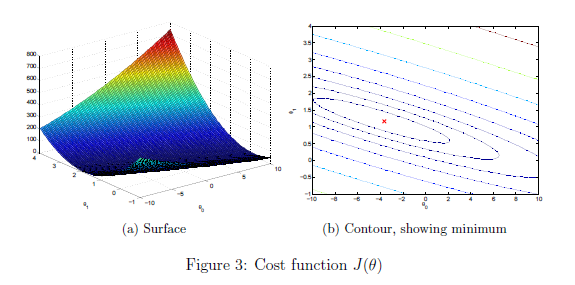

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\text{ }\left(x^{\left(1\right)} \right)}^T -\\
{-\text{ }\left(x^{\left(2\right)} \right)}^T -\\
\vdots \text{ }\\
{-\text{ }\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \text{           }\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \text{ }\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f\n%f',theta(1), theta(2), theta(3))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

price = [1, (1650 - mu(1)) / sigma(1), (3 - mu(1)) / sigma(2)] * theta; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

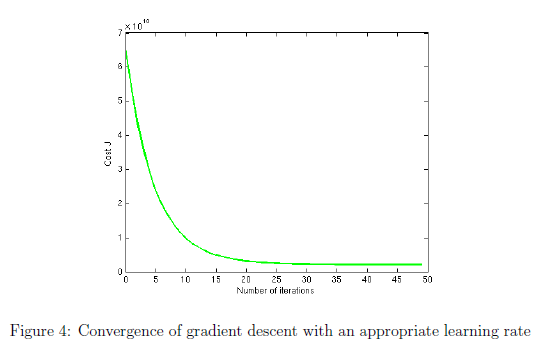

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \text{ }\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 0.1;
num_iters = 100;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 100;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f',theta(1),theta(2))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = [1, (1650 - mu(1)) / sigma(1), (3 - mu(1)) / sigma(2)] * theta; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f', theta(1),theta(2));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = [1, (1650 - mu(1)) / sigma(1), (3 - mu(1)) / sigma(2)] * theta; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

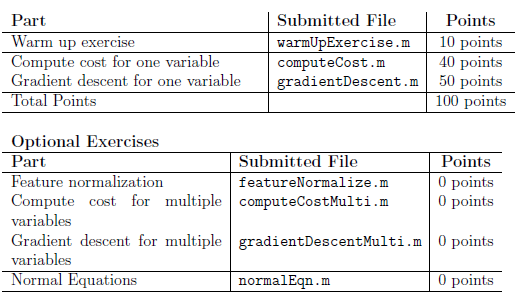

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.